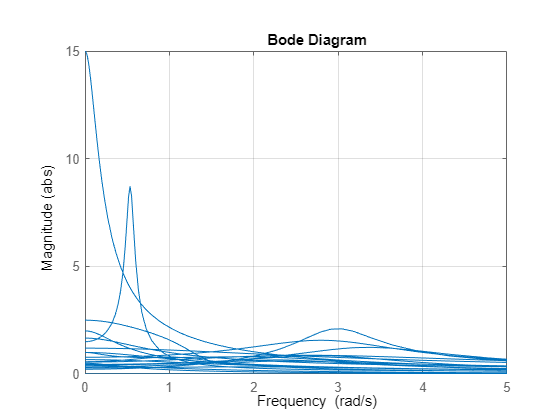

% transfer functions
W1 = [
    tf([2,7],[1,2,9]), tf([2,-5],[1,2,12]), tf([1,-2],[1,4,7]), tf([2],[1,6,5]);
    tf([1,-2],[1,3,1]), tf([3,15],[2,7,1]),  tf([1,1,-3],[1,7,1,2]), tf([5,2],[1,3,8,2]);
    tf([3,4],[5,6,7]), tf([2,5],[1,5,3]), tf([1],[1,1]), tf(0);
    tf([6],[2,5]),  tf([1,2],[1,2,6]), tf([2,2],[1,1,9]), tf([1,4],[1,2,9]);
    tf([2,1,5],[1,2,3,2]), tf([3,-5],[1,4,9]),  tf([1],[1,5,2]), tf([2],[2,3]);
    ];
W2 = [
    tf([7],[1,3,2]), tf([6],[2,8,9]), tf([12,3],[1,5,1]),  tf(0), tf([3,9, 1],[1,9,9, 2]);
    tf([4,7],[1,3,5]), tf([2],[1,1]), tf(0), tf([13],[3,5,7]), tf([3],[1,3,4]);
   tf([1,1],[1,2,1]), tf([2,-2],[1,20,2]),tf([9],[1,15,2]), tf([10,2],[1,2,3]), tf([3,2,1],[1, 2,15,6]);
     tf([5,4],[30,3,1]), tf([6,5],[1,8,2]),  tf([1, 2],[1,2,8]),  tf([2,0],[1,3,4]), tf([1],[1,5,7]);
     ];

% plot amplitude frequency response
ampW1 = bodeplot(W1);
setoptions(ampW1,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off', 'IOGrouping','all');
xlim([0 5]);

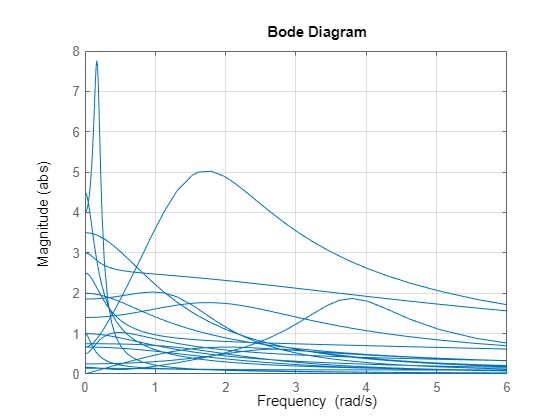

ampW2 = bodeplot(W2);
setoptions(ampW2,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off','IOGrouping','all');
xlim([0 6]);

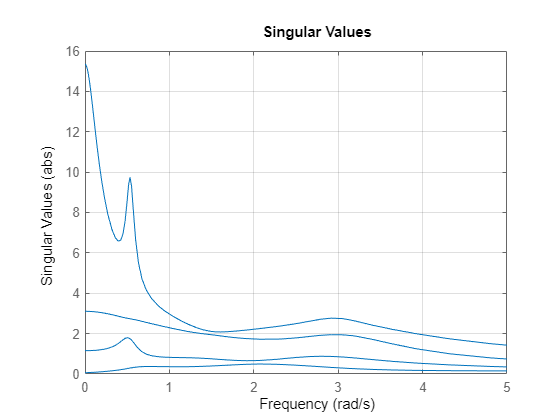


% plot singular values to frequency
sinValW1 = sigmaplot(W1);
setoptions(sinValW1,'FreqScale','linear','MagUnits','abs','Grid','on');
xlim([0 5]);

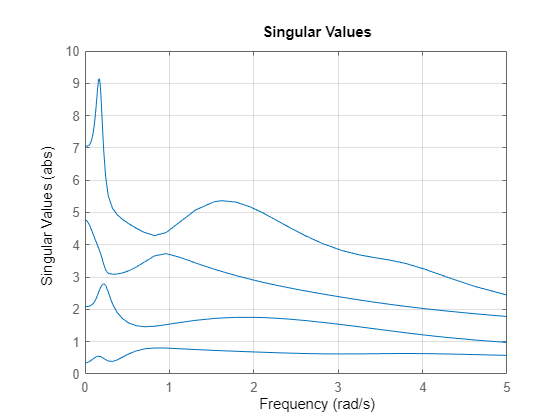

sinValW2 = sigmaplot(W2);
setoptions(sinValW2,'FreqScale','linear','MagUnits','abs','Grid','on');
xlim([0 5]);

% find h_2 norm
getPeakGain(W1)

ans = 15.3440

getPeakGain(W2)

ans = 9.1502


% find h_inf norm
norm(W1)

ans = 6.1105

norm(W2)

ans = 8.1696